Reset

clear

Constants

Ts = 0.001;
gstr = 1000;
carrier = 50;
bandwidth = 10;

Data generation

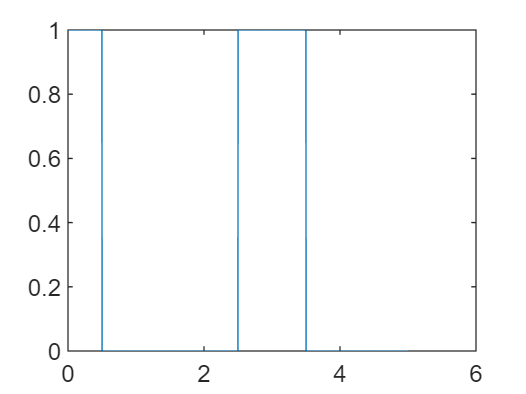

t = 0:Ts:5-Ts;
data = (rectangularPulse(t) + rectangularPulse(t - 3));
datagaus = conv(gausswin(gstr), data);
datagaus = datagaus(1:length(t));
plot(t, data)

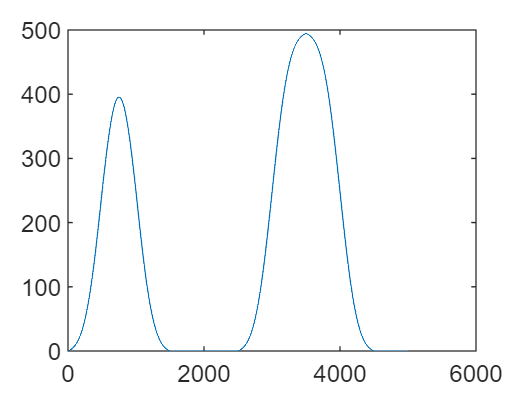

plot(datagaus)

Modulation

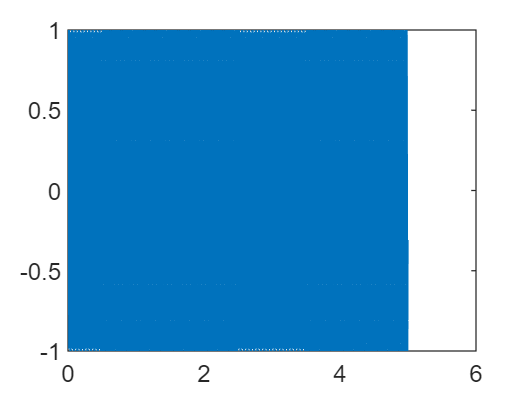

RFsignal = sin((carrier + bandwidth.*data).*2.*pi.*t);
RFsignalgaus = sin((carrier + bandwidth.*datagaus).*2.*pi.*t);
plot(t, RFsignal)

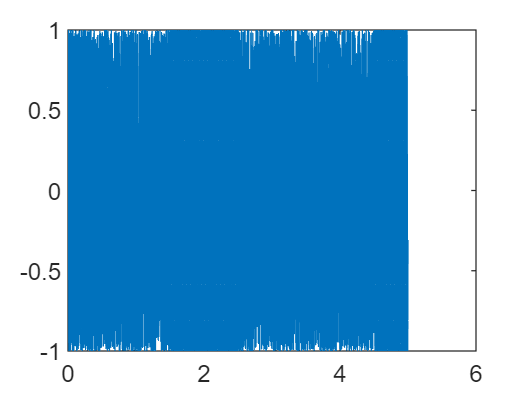

plot(t, RFsignalgaus)

FFT analysis

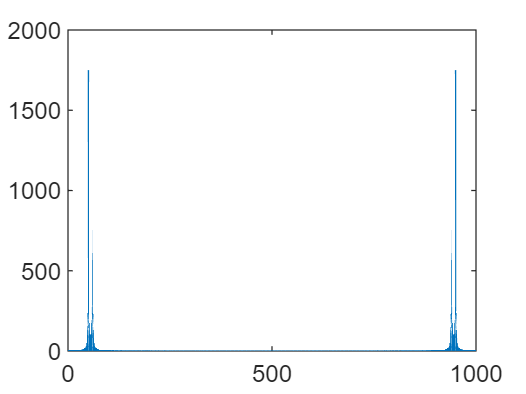

RFsignalfreq = fft(RFsignal);
RFsignalfreqgaus = fft(RFsignalgaus);
fs = 1/Ts;
f = (0:length(RFsignalfreq)-1)*fs/length(RFsignalfreq);
plot(f, abs(RFsignalfreq))

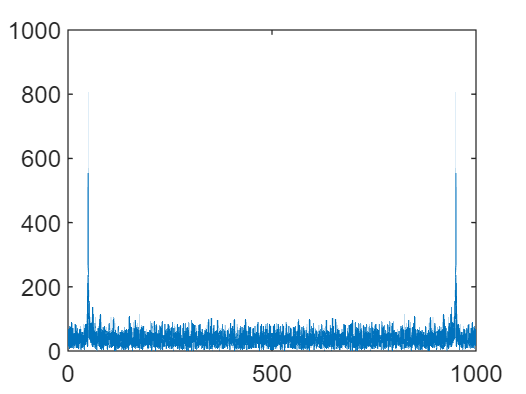

plot(f, abs(RFsignalfreqgaus))

Demodulation